**Taller 2**

**Path-based1**

clc;
clear all;
rng(0);
datos = importdata("pathbased.txt");
X = datos(:,1:2);

% Diagrama de codo kmeans
fprintf("kmeans");

kmeans

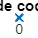

n = 20;
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

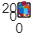


k=15;
idx = kmeans(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


fprintf("kmeans");

kmeans

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 2.0846

SSB = 9.1903

WB = 3.4024

SIL = 0.5426


fprintf("kmedoids");

kmedoids

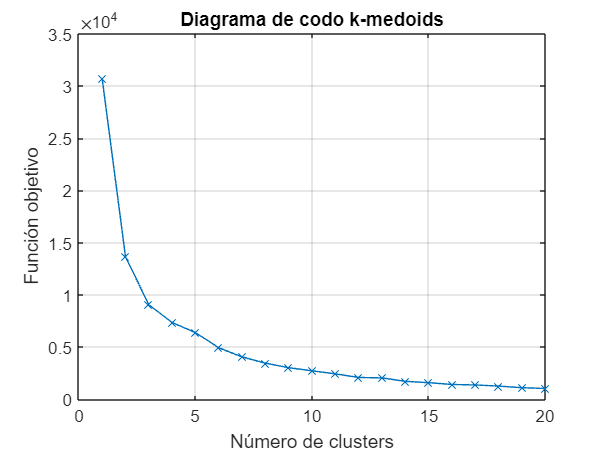


% Diagrama de codo kmedoids
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

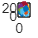


k=15;
idx = kmedoids(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 2.0108

SSB = 9.1714

WB = 3.2887

SIL = 0.5730


fprintf("DBSCAN");

DBSCAN


ep = clusterDBSCAN.estimateEpsilon(X,2,10)

ep = 1.8213

idx = dbscan(X,ep,10);
k1 = max(idx);
idx(idx==-1)= k1+1;
idx(idx==0)= k1+2;
k0 = min(idx)

k0 = 1

k1 = max(idx)

k1 = 3

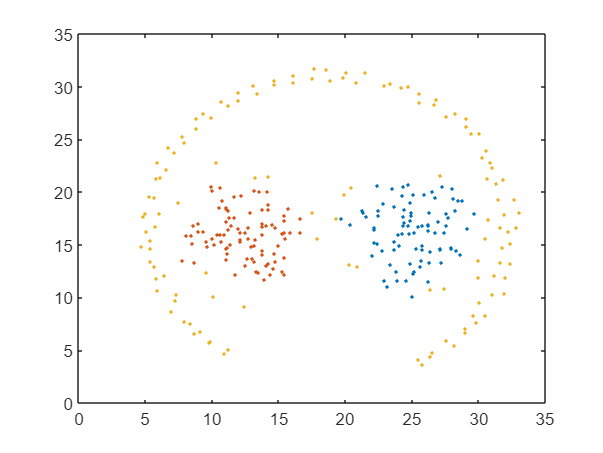


figure;
for i=k0:k1
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 7.0103

SSB = 4.3779

WB = 4.8038

SIL = 0.2273